# Calculo de la probabilidad de error Con cambios en:

% Condiciones climaticas
% Esquemas de modulación
% Potencia transmitida


%% Ecuación General


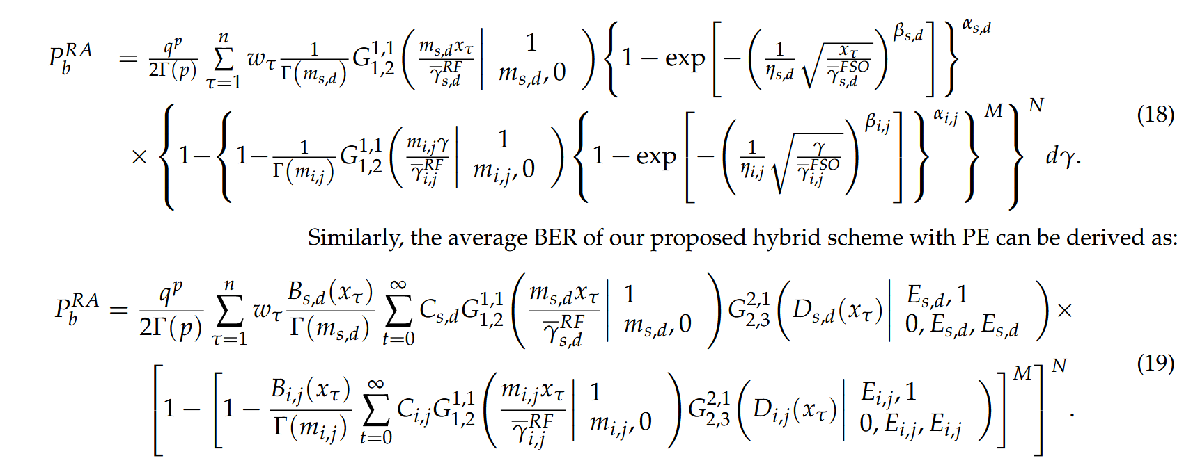


%%Parametros
% Modulación Coherent binary phase shift keying (CBPSK)
p1 = 0.5;
q1 = 1;
% Modulación Differential binary phase shift keying (DBPSK)
p2 = 1;
q2 = 1;
% Modulación Coherent binary frequency shift keying(CBFSK) 
p3 = 0.5;
q3 = 0.5;
% Modulación Non-coherent binary frequency shift keying (NBFSK)
p3 = 1;
q3 = 0.5;




## Weibull

% Alpha
a = 4.19

a = 4.1900

% Beta
b = 1.49

b = 1.4900

%eta 
e = 0.62

e = 0.6200

## Geometria

% Cantidad de Drones y enlaces
M = 3;
N = 4;
% Apertura de la antena D_xy
Dxy = 0.01; 
% Axy

Axy = (pi.*Dxy.^2)./4;

% Lxy
Lxy = 1 %km

Lxy = 1


% Theta
thetaxy = 0.001 %rad

thetaxy = 1.0000e-03


% m 
m = 0.5

m = 0.5000

## Cambios de condiciones

woxg = 15.1 %dBm

woxg = 15.1000

wrain = 0

wrain = 0

% Aire Limpio
wFSOair = 0.43

wFSOair = 0.4300



% Neblina
wFSOneb = 4.2

wFSOneb = 4.2000

% Neblina ligera
wFSOneblig = 7.7

wFSOneblig = 7.7000

% Lluvia ligera
wFSOlluv = 1.98

wFSOlluv = 1.9800

wrainlluv = 1.50

wrainlluv = 1.5000

## Calculo del SNR


%Gains
Gtxy = 44 %dBi

Gtxy = 44

Grxy = 44 %dBi

Grxy = 44


% Lambda
lambdarf = 5.*10.^-9;

% FSO
sigmafso = 10.*10.^-14 % A2/Hz Está al cuadrado

sigmafso = 1.0000e-13

gfso = (Axy./(pi.*thetaxy.*Lxy)).*exp(wFSOair.*Lxy)

gfso = 3.8431

gammafsoprom = 1.*gfso.*p1/sigmafso;
% RF
sigmarf = -85 %dBm

sigmarf = -85

grf = Gtxy + Grxy - 20.*log10((4.*pi.*Lxy)./lambdarf) - Lxy.*(woxg + wrain)

grf = -115.1048

gammarfprom = 1.*grf./sigmarf;


## Ecuación

BER = 0

BER = 0

sumatoria = 0;
w = [4.5300, 3.81616, 5.079, 8.065]

w =     4.5300    3.8162    5.0790    8.0650


x = [5.2352, 2.1566, 5.137, 1.108]

x =     5.2352    2.1566    5.1370    1.1080



for tau = 1:4
    
    % ---- Primer término (en s,d) ----
    G_sd = meijerG(1,[],[],[0.5,0], (m * x(tau)) / gammarfprom);
    term1 = (1 / gamma(m)) * G_sd * (1 - exp(- (1/e) * sqrt(x(tau) / gammafsoprom))^b)^a;
    
    % ---- Segundo término (en i,j) ----
    G_ij = meijerG(1,[],[],[m,0], (m * x(tau)) / gammarfprom);
    term2 = (1 - (1 - (1 / gamma(m)) * G_ij * ...
        (1 - exp(- (1/e) * sqrt(x(tau) / gammafsoprom))^b)^a )^M )^N;
    
    % ---- Producto con pesos ----
    sumatoria = sumatoria + w(tau) * term1 * term2;
end

% ---- Ecuación final ----
BER = (q1^p1 / (2 * gamma(p1))) * sumatoria;


## Clear Air

BERairCBPSK = zeros(1,25);
Power = -30:1:-5;
for P1 = -30:-5
P1w = 10.^((P1-30)./10);
gfso = (Axy./(pi.*thetaxy.*Lxy).^2).*exp(wFSOair.*Lxy)
gammafsoprom = P1w.*gfso.*p1/sigmafso;
% RF
sigmarf = -85 %dBm
grf = Gtxy + Grxy - 20.*log10((4.*pi.*Lxy)./lambdarf) - Lxy.*(woxg + wrain)
gammarfprom = P1.*grf./sigmarf;
gammarfpromw = 10.^((gammarfprom-30)./10);

sumatoria = 0;
w = [4.5300, 3.81616, 5.079, 8.065];
x = [5.2352, 2.1566, 5.137, 1.108];

for tau = 1:4
    
    % ---- Primer término (en s,d) ----
    G_sd = (double(meijerG(1,0,[0.5,0],0, (m * x(tau)) / gammarfpromw)));
    term1 = (1 / gamma(m)) * G_sd * (1 - exp(- (1/e) * sqrt(x(tau) / gammafsoprom))^b)^a;
    
    % ---- Segundo término (en i,j) ----
    G_ij = (double(meijerG(1,0,[m,0],0, (m * x(tau)) / gammarfpromw)));
    term2 = (1 - (1 - (1 / gamma(m)) * G_ij * ...
        (1 - exp(- (1/e) * sqrt(x(tau) / gammafsoprom))^b)^a )^M )^N;
    
    % ---- Producto con pesos ----
    sumatoria = sumatoria + w(tau) * term1 * term2
end

% ---- Ecuación final ----
BERairCBPSK(P1+31) = abs((q1^p1 / (2 * gamma(p1))) * sumatoria);



end

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0

gfso = 1.2233e+03

sigmarf = -85

grf = -115.1048

sumatoria = 0

sumatoria = 0

sumatoria = 0

sumatoria = 0